clear;clc;
close all;

% Download data used in the ACM 2013 paper
downloadData = false;
if downloadData
    websave('feds200628.xls', 'https://www.federalreserve.gov/econresdata/researchdata/feds200628.xls')
end
tb = readtable('feds200628.xls');
tb.Var1 = datetime(tb.Var1);

tt = table2timetable(tb(:,2:end), 'RowTimes', tb.Var1)

tt = 14557×99 timetable
       Time        SVENY01    SVENY02    SVENY03    SVENY04    SVENY05    SVENY06    SVENY07    SVENY08    SVENY09    SVENY10    SVENY11    SVENY12    SVENY13    SVENY14    SVENY15    SVENY16    SVENY17    SVENY18    SVENY19    SVENY20    SVENY21    SVENY22    SVENY23    SVENY24    SVENY25    SVENY26    SVENY27    SVENY28    SVENY29    SVENY30    SVENPY01    SVENPY02    SVENPY03    SVENP

% Extract the Svenson model parameters and dates matching the range from
% the paper. Extrapolate where needed so that we have one data point for
% each month.
TR = timerange(datetime(1987, 1, 1), datetime(2011, 12, 31));
tt = tt(TR,["SVENY02", "BETA0", "BETA1", "BETA2", "BETA3", "TAU1", "TAU2"]);
tt = retime(tt, 'monthly', 'nearest');
tt(end, :) = [];

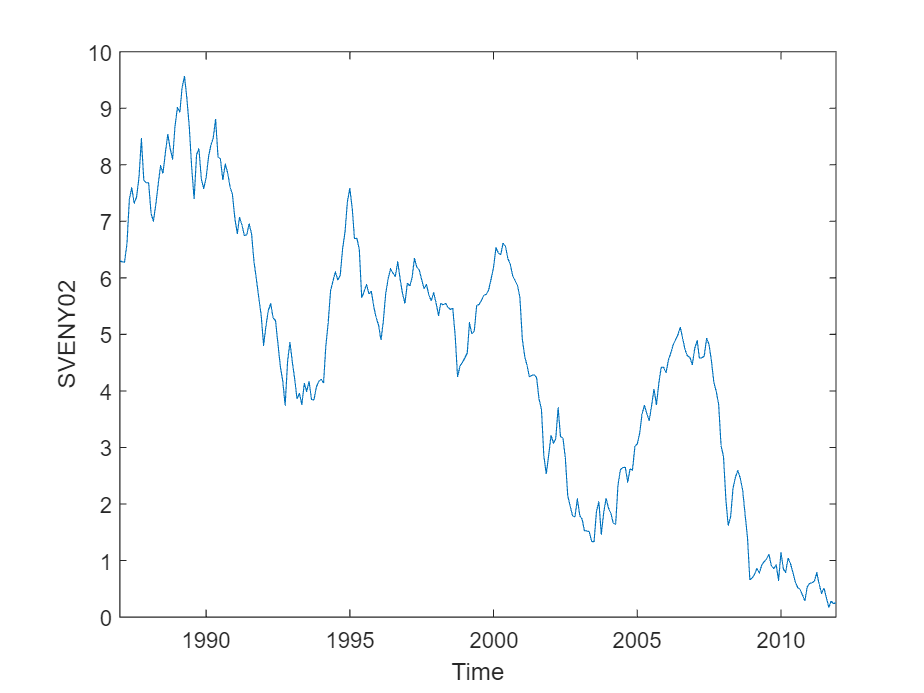

figure; plot(tt, "SVENY02")

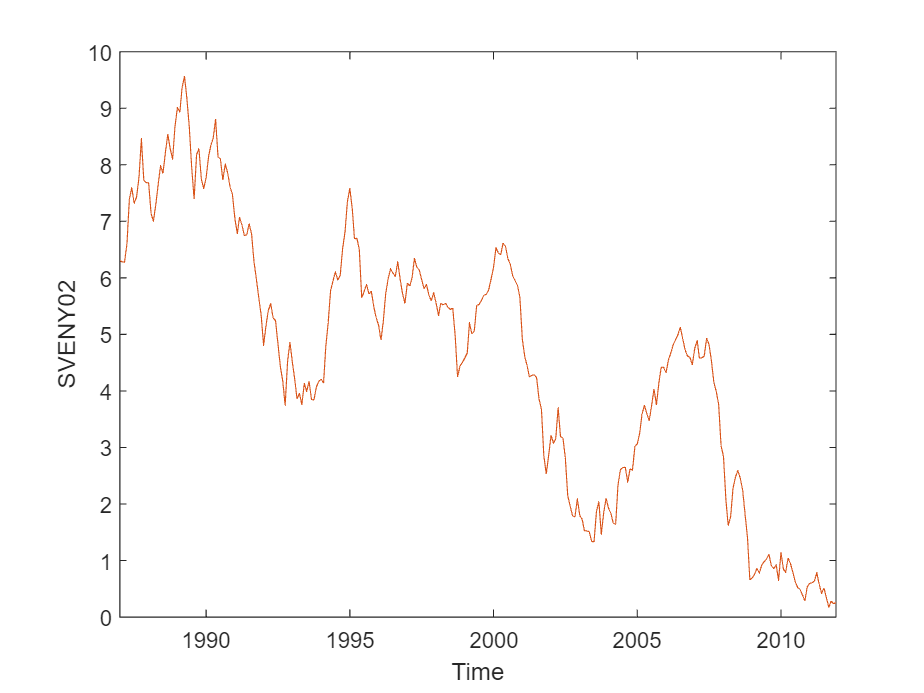

% Extract parameters from table
Beta0 = tt.BETA0;
Beta1 = tt.BETA1;
Beta2 = tt.BETA2;
Beta3 = tt.BETA3;
Tau1 = tt.TAU1;
Tau2  = tt.TAU2;
maturities = (1:120)/12;

% Compute yields using the Svenson model
yields = zeros(height(tt),numel(maturities));
for i = 1 : height(tt)
    s = Beta0(i) + ...
    Beta1(i).*(1 - exp(-maturities/Tau1(i))).*(Tau1(i)./maturities) + ...
    Beta2(i)*((1-exp(-maturities/Tau1(i))).*Tau1(i)./maturities-exp(-maturities./Tau1(i))) + ...
    Beta3(i)*((1-exp(-maturities./Tau2(i))).*(Tau2(i)./maturities) - exp(-maturities/Tau2(i)));
    yields(i,:) = s;
end
ttest = array2timetable(yields, RowTimes=tt.Time);

stir = timetable(ttest{:,1}/12, RowTimes = ttest.Time);
hold on
plot(ttest.Time, ttest{:,24})

% Model options
numFactors = 5;                   % Number of factors

%************************************************************************************************
% Data
%************************************************************************************************
% Specify maturity vectors
nMax    = 120;              % Maximum maturity (in months)
matsAll = 1:nMax;           % Vector of all maturities up to nMax
pcMats  = 3:120;           % Maturities used to compute the pricing factors
rxMats  = [6:6:60,84,120];  % Maturities used for the return regressions
nrx     = size(rxMats,2);   % Number of excess returns in the return regressions
model   = "meanzero";      % Type of model

[decomposition, lambda0, lambda1, ~, delta1, tsquared] = estimateACM(...
    ttest, ...
    stir, ...
    matsAll, ...
    numFactors, ...
    pcMats = pcMats, ...
    rxMats = rxMats, ...
    model = model)

decomposition = struct with fields:
           yHat: [300×120 double]
       expected: [300×120 double]
    riskPremium: [300×120 double]
      convexity: [300×120 double]


lambda0 =    -0.4318
   -0.0498
   -0.0228
   -0.0113
    0.0001


lambda1 =    -0.0039    0.0934   -0.1048   -1.4854    5.8620
   -0.0046   -0.0109    0.0063   -0.1491   -0.6248
   -0.0026    0.0003   -0.0942    0.4614   -0.2769
   -0.0008   -0.0001   -0.0046   -0.0398    0.3381
   -0.0005   -0.0002   -0.0021    0.0418   -0.3091


delta1 = 1.0e-03 *

    0.0788
    0.1768
    0.3225
    0.6744
    0.8662


tsquared =    11.6576
    7.5184
    9.3534
    7.9811
   95.2377
   37.3644
    6.9605
    8.3446
   10.3807
   14.1930


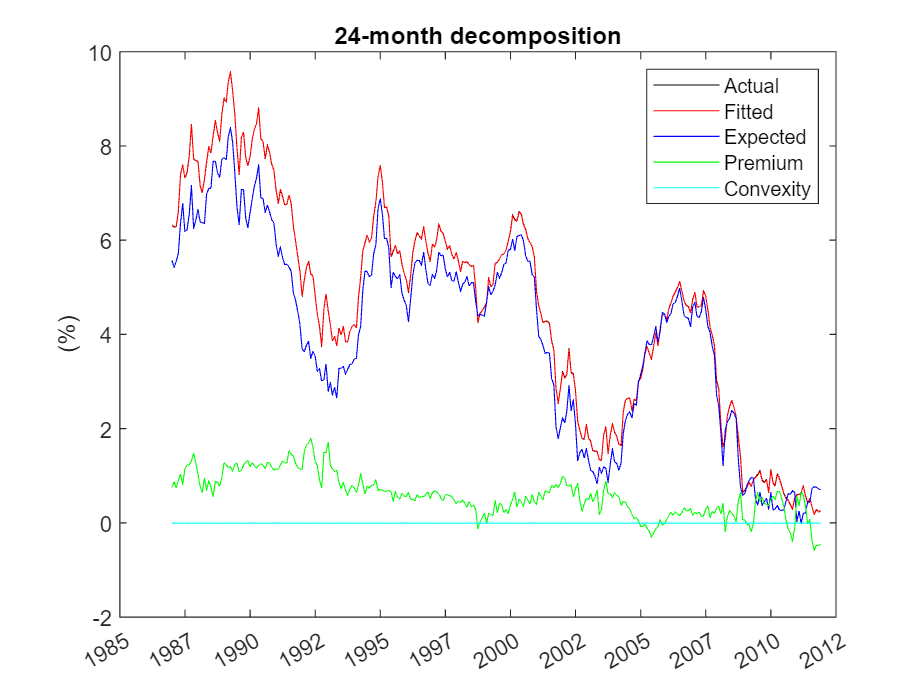

% Plot i-month decomposition
i = 24;
figure
plot(tt.Time,ttest{:,i},'k')
hold on
plot(tt.Time,decomposition.yHat(:,i),'r')
plot(tt.Time,decomposition.expected(:,i),'b')
plot(tt.Time,decomposition.riskPremium(:,i),'g')
plot(tt.Time,decomposition.convexity(:,i),'c')
legend('Actual','Fitted','Expected','Premium','Convexity')
ylabel('(%)')
datetick('x','yyyy')
title(i + "-month decomposition")

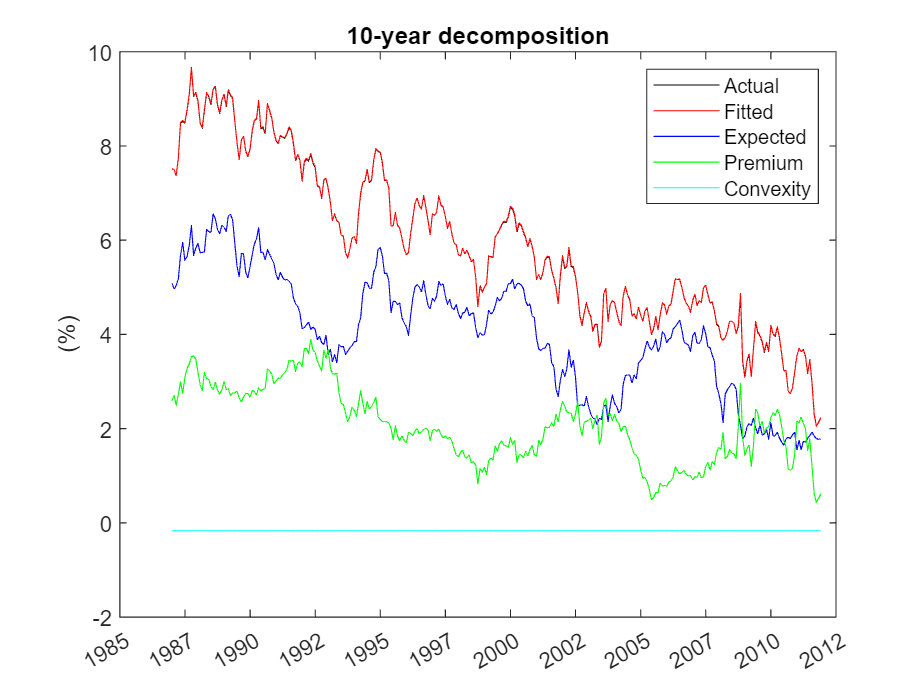

% Plot 10-year decomposition
figure
plot(tt.Time,ttest{:, end},'k')
hold on
plot(tt.Time,decomposition.yHat(:,end),'r')
plot(tt.Time,decomposition.expected(:,end),'b')
plot(tt.Time,decomposition.riskPremium(:,end),'g')
plot(tt.Time,decomposition.convexity(:,end),'c')
legend('Actual','Fitted','Expected','Premium','Convexity')
ylabel('(%)')
datetick('x','yyyy')
title('10-year decomposition')